clear all
load fisheriris


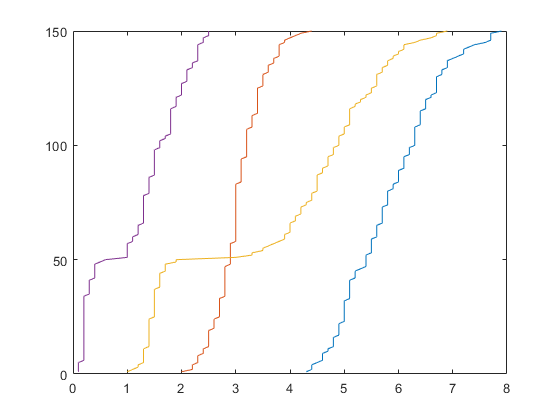

rng('default')
% rand(2,2);
[C,ia,ic] = unique(species);

y = [ic==1 ic==2 ic==3];
indexez= randperm(150);

plot(sort(meas()),(1:150))

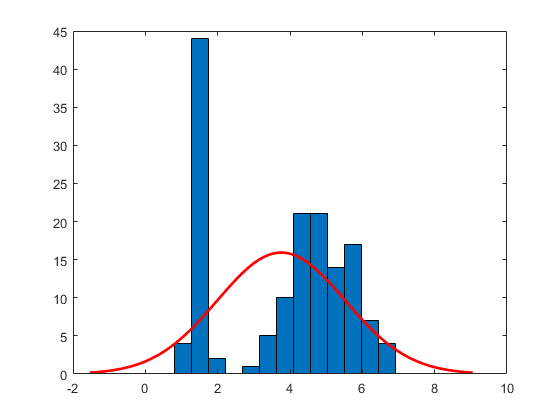

histfit((meas(:,3)))

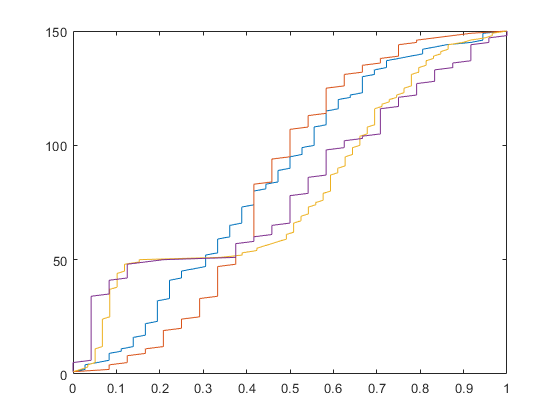


input = normalize(meas(indexez,:),'range');
plot(sort((input)), 1:150)

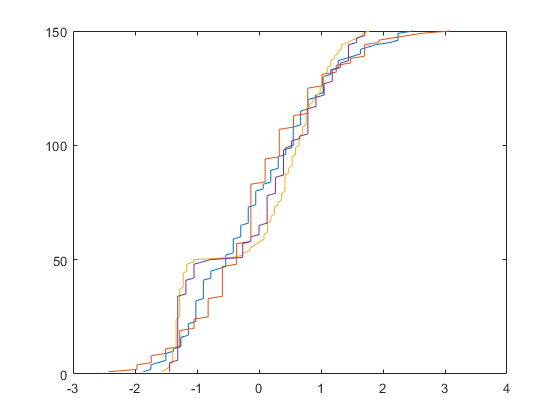


output = y(indexez,:);

input2 = normalize(meas(indexez,:));

g = (1 + exp(-1 * input2)) .^ -1;

plot(sort((input2)), 1:150)

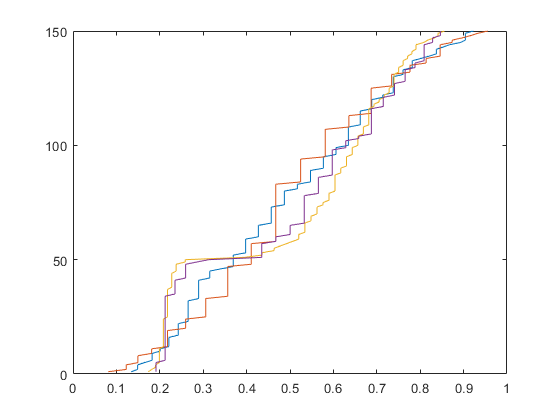

plot(sort((g)), 1:150)


testinput = g((end-49):end,:);
testoutput = output((end-49):end,:);

batchsize = 100;

in = g(1:batchsize,:);
out = output(1:batchsize,:);

n = 1;


knots = 10

knots = 10

M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

N_a=zeros(batchsize,knots+2);
N_b=zeros(batchsize,knots+2);
N_c=zeros(batchsize,knots+2);
N_d=zeros(batchsize,knots+2);

B=[];
C=[];


% Vandermonde ----------

for i = 1:batchsize
    
    index_a(i)= floor((in(i,1)*knots+(10*knots*eps)))+1;
    index_b(i)= floor((in(i,2)*knots+(10*knots*eps)))+1;
    index_c(i)= floor((in(i,3)*knots+(10*knots*eps)))+1;
    index_d(i)= floor((in(i,4)*knots+(10*knots*eps)))+1;
    
    Ntemp_a = (mod(in(i,1),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_b = (mod(in(i,2),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_c = (mod(in(i,3),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_d = (mod(in(i,4),1/knots)*knots).^linspace(2,0,3)*M';
    
    N_a(i,index_a(i):index_a(i)+2) = Ntemp_a;
    N_b(i,index_b(i):index_b(i)+2) = Ntemp_b;
    N_c(i,index_c(i):index_c(i)+2) = Ntemp_c;
    N_d(i,index_d(i):index_d(i)+2) = Ntemp_d;
  
f= outproduct( N_a(i,:), N_b(i,:), N_c(i,:), N_d(i,:));
    
B(i,:)=f(:)';
    
% a=in(i,1).^[0:n];  % a = a/norm(a);
% b=in(i,2).^[0:n];  % b = b/norm(b);
% c=in(i,3).^[0:n];  % c = c/norm(c);
% d=in(i,4).^[0:n];  % d = d/norm(d);
% 
% f= outproduct(a,b,c,d);
% B(i,:)=f(:)';
end
% ----------- ----------


training logistic sigmoid

w = randn([(knots+2)^4 3])/100;



alpha=1;

tic
for i= 1:2
z1 = B*w;

expp = exp(z1-max(z1,[],1));
p1 = expp./sum(expp,2);
sum(p1,2);
% p1 = max(min(p1, 0.95),0.05);
d1 = p1-out;

w = pinv(B)*(z1-alpha*d1);
end
toc

Elapsed time is 0.168183 seconds.


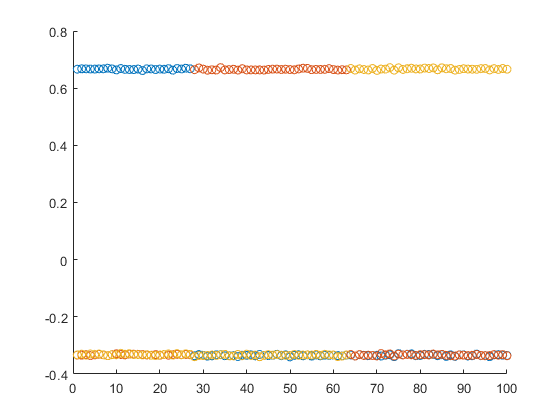


zy = z1; % B*w;
ay = p1;

zet=[];
zet(indexez(1:batchsize),:)=zy(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

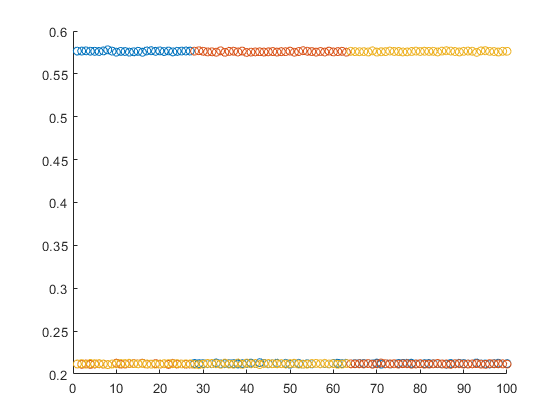


zet=[];
zet(indexez(1:batchsize),:)=ay(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

% TEST set


% Vandermonde ----------test
Btest=[];
N_a=zeros(batchsize,knots+2);
N_b=zeros(batchsize,knots+2);
N_c=zeros(batchsize,knots+2);
N_d=zeros(batchsize,knots+2);
for i = 1:50

     testindex_a(i)= floor((testinput(i,1)*knots+(10*knots*eps)))+1;
     testindex_b(i)= floor((testinput(i,2)*knots+(10*knots*eps)))+1;
     testindex_c(i)= floor((testinput(i,3)*knots+(10*knots*eps)))+1;
     testindex_d(i)= floor((testinput(i,4)*knots+(10*knots*eps)))+1;
    
    Ntemp_a = (mod(testinput(i,1),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_b = (mod(testinput(i,2),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_c = (mod(testinput(i,3),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_d = (mod(testinput(i,4),1/knots)*knots).^linspace(2,0,3)*M';
    
    N_a(i,testindex_a(i):testindex_a(i)+2) = Ntemp_a;
    N_b(i,testindex_b(i):testindex_b(i)+2) = Ntemp_b;
    N_c(i,testindex_c(i):testindex_c(i)+2) = Ntemp_c;
    N_d(i,testindex_d(i):testindex_d(i)+2) = Ntemp_d;
  
f= outproduct( N_a(i,:), N_b(i,:), N_c(i,:), N_d(i,:));
    
Btest(i,:)=f(:)';

end


zytest = Btest*w;

resizen = size(w);

wtensor = reshape(w,[(knots+2)*[1 1 1 1] 3]);
[G, rk] = ttsvd(wtensor,0.000001)

G = 5×1 cell array
    { 1×12×10 double}
    {10×12×49 double}
    {49×12×25 double}
    {25×12×3  double}
    { 3×3     double}


rk =      1
    10
    49
    25
     3



suz=0;
for k=1:length(G)
    suz = suz + numel(G{k});
end

recon = tcontract(G);

zytest = Btest*reshape(recon,resizen);

exppy = exp(zytest-max(zytest,[],2));
pytest = exppy./sum(exppy,2);

[M, I] = max(pytest,[],2); 

misclassif = ~(I==ic(indexez(101:150)));
sum(abs(misclassif))/50

ans = 0.0200

sum(abs(pytest-testoutput), 'all')/(150)

ans = 0.2378


C = confusionmat(I,ic(indexez((end-49):end)))

C =     23     0     0
     0    13     0
     0     1    13


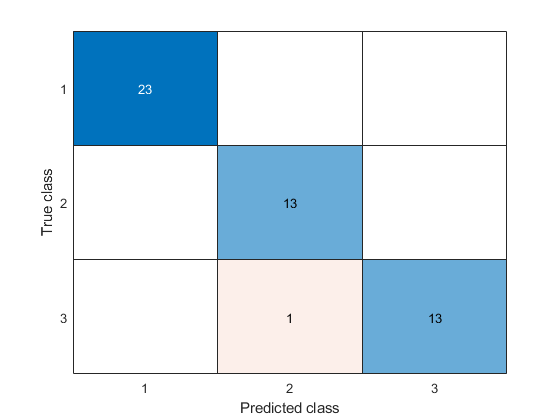

confusionchart(C);

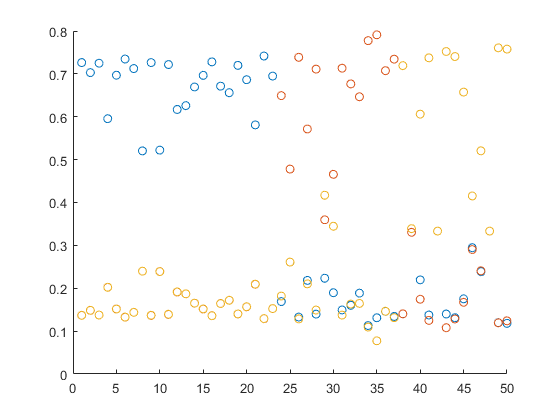


% scatter(1:50,misclassif);
figure;
zet=[];
zet(indexez((end-49):end),:)=pytest(1:end,:);
zet = zet(any(zet,2),:);

hold on
scatter(1:50,zet(:,1))
scatter(1:50,zet(:,2))
scatter(1:50,zet(:,3))
hold off



% rataa = norm(y-output)/norm(output)



wplot = reshape(w(:,1),(knots+2)*[1 1 1 1])

wplot = wplot(:,:,1,1) =

   1.0e+03 *

    1.2866   -1.2943    4.6046
    0.7050   -0.0350   -0.4978
    2.6190   -0.5966    2.2095


wplot(:,:,2,1) =

   1.0e+03 *

   -0.0674    0.7460   -3.1106
   -1.0074    0.0899    0.4219
    3.5228   -0.6939    0.1962


wplot(:,:,3,1) =

   1.0e+04 *

   -1.2521    0.2606   -0.4003
    0.7087   -0.1658    0.2060
   -2.2429    0.5796   -0.9031


wplot(:,:,1,2) =

   1.0e+03 *

   -2.5621    1.0407   -2.8337
    0.7598   -0.1881    0.4337
   -5.4971    1.2962   -2.4644


wplot(:,:,2,2) =

   1.0e+03 *

    1.3449   -0.6914    2.1407
   -0.1545    0.0972   -0.4004
    0.5585   -0.2139    0.7365


wplot(:,:,3,2) =

   1.0e+03 *

   -1.0992    0.8943   -2.3079
   -0.4863    0.0180    0.3145
    1.4888   -0.2862    0.0092


wplot(:,:,1,3) =

   1.0e+04 *

   -0.3013    0.0477    0.2093
    0.0333   -0.0458    0.2176
    1.5911   -0.3826    0.6707


wplot(:,:,2,3) =

   1.0e+03 *

   -3.0144    1.8696   -7.9792
    0.2359   -0.1903    0.9446
   -2.376


% surf(1:knots+1,1:knots+2,wplot(:,:,1,1))
% surf(input(:,1),input(:,2),double(rehape(y(:,1), []))

xx=in(:,1)

xx =     0.9040
    0.2895
    0.3693
    0.2895
    0.2895
    0.3978
    0.5769
    0.3978
    0.7378
    0.9040


yy=in(:,2)

yy =     0.3565
    0.2178
    0.6870
    0.6870
    0.8137
    0.9322
    0.4672
    0.2594
    0.4672
    0.2594


zz=double((out(:,3)))

zz =      1
     0
     0
     0
     0
     0
     0
     0
     1
     1


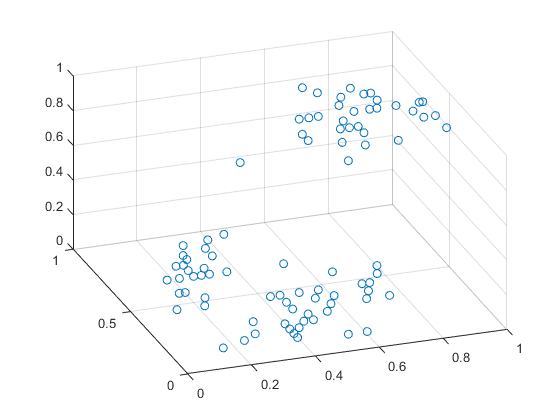

scatter3(xx,yy,zz)


zz=double((output(:,3)))

zz =      1
     0
     0
     0
     0
     0
     0
     0
     1
     1


zz=p1(:,3)

zz =     0.5483
    0.1983
    0.1908
    0.1925
    0.1941
    0.1903
    0.2008
    0.1822
    0.5547
    0.5488


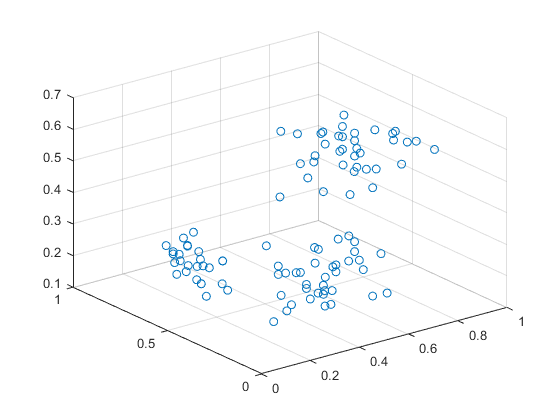


% zz=input(:,3)
% plot3(xx,yy,zz,'.-')
scatter3(xx,yy,zz)

% ii=1
% for re = logspace(-10,-0.5)
% [G, rk] = ttsvd(wplot,re)
% suz=0
% for k=1:4
%     suz = suz + numel(G{k});
% end
% 
% numberelements = numel(wplot)
% 
% numberelements/suz
% recon = tcontract(G);
% 
% 
% ploto(ii) = sum(abs(recon-wplot),'all')/numberelements
% 
% plotosuz(ii)=suz
% ii=ii+1;
% end
% 
% plot(ploto)
% plot(plotosuz)